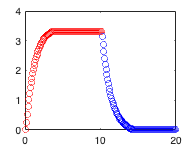

clc
clear
close all
charge = importdata("chargingLog.txt");
discharge = importdata("discharge.txt");
%data = importdata("data_modelling\voltageLog.txt");
%charge(1:101,:)=data(1:101,:);
%discharge(1:100,:)=data(102:end,:);
plot(charge(:,1),charge(:,2),'ro',discharge(:,1),discharge(:,2),'bo')
hold on

fo1=fitoptions('Method','NonlinearLeastSquares','StartPoint',[3 1],'Lower',[0 0],'Upper',[5 25]);
model1=fittype( @(V0, tau, x) V0.*(1-exp(-x./tau)),'options',fo1);
[RCfitcha, gof]=fit(charge(:,1),charge(:,2),model1)

RCfitcha =      General model:
     RCfitcha(x) = V0.*(1-exp(-x./tau))
     Coefficients (with 95% confidence bounds):
       V0 =       3.338  (3.318, 3.358)
       tau =       1.135  (1.098, 1.173)

gof = struct with fields:
           sse: 0.6127
       rsquare: 0.9881
           dfe: 100
    adjrsquare: 0.9880
          rmse: 0.0783


xRC1=0:0.05:9.5;
yRC1=RCfitcha(xRC1);
fo2=fitoptions('Method','NonlinearLeastSquares','StartPoint',[0 1],'Lower',[0 0],'Upper',[25 5]);
model2=fittype( @(t02, tau2, x) 3.3.*exp(-(x-t02)./tau2),'options',fo2);
[RCfitdischa, gof]=fit(discharge(:,1),discharge(:,2),model2)

RCfitdischa =      General model:
     RCfitdischa(x) = 3.3.*exp(-(x-t02)./tau2)
     Coefficients (with 95% confidence bounds):
       t02 =       10.24  (10.23, 10.25)
       tau2 =       1.079  (1.066, 1.092)

gof = struct with fields:
           sse: 0.0559
       rsquare: 0.9988
           dfe: 96
    adjrsquare: 0.9988
          rmse: 0.0241


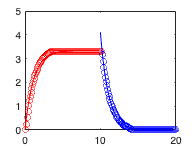

xRC2=10:0.05:19.5;
yRC2=RCfitdischa(xRC2);
plot(xRC1,yRC1,'r-',xRC2,yRC2,'b-')

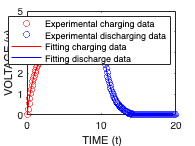

xlabel("TIME (t)")
ylabel("VOLTAGE (v)")
legend("Experimental charging data","Experimental discharging data","Fitting charging data","Fitting discharge data")